# Expand Example 2.13:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider the RLC circuit shown below:

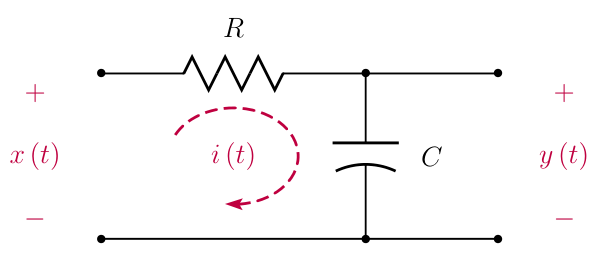

Let the initial value of the output signal be $y(0)=V_{0}$.  The homogeneous solution of the differential equation (or the natural response of the system) is


$$y_{h}(t)=V_{0}\,e^{-t/RC}\,u(t)$$


The time constant for this circuit is $\tau=RC$.  Let $V_{0}=5$.  Compute and graph the natural response for selected values of parameters $R$ and $C$.  Indicate the time constant and related critical values on the graph.

R = 1;  % Resistance
C = 1;  % Capacitance

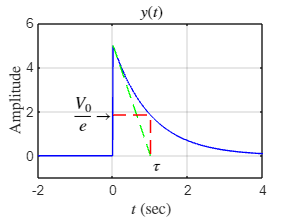

tau = R*C;         % Time constant
t = [-2:0.01:4];   % Vector of time instants
V0 = 5;            % Initial value of the output signal
% Compute the natural response as given by Eqn. (2.82)
y = V0*exp(-t/tau).*(t>=0);
% Graph the natural response
% Also show the tangent at t=0 and the value at t=tau
plot(t,y,'b-',...                 % Signal
     [0,tau],[V0,0],'g--',...     % Tangent line
     [0,tau,tau],V0/exp(1)*[1,1,0],'r--'); grid;
set(0,'defaultTextInterpreter','latex');
text(tau,0,'$\tau$','VerticalAlignment','top');
text(0,V0/exp(1),'$\frac{V_{0}}{e}\rightarrow$','HorizontalAlignment','right');
axis([-2,4,-1,6]);
title('$y(t)$');
xlabel('$t$ (sec)'); 
ylabel('Amplitude');

set(0,'defaultTextInterpreter','tex');